# P2 Antigas

Resolução das questões dde frequência do arquivo coletanea_questoes_prova.pdf que está no moodle. As questão serão nomeadas pela página em que estão no pdf.

## pg 11

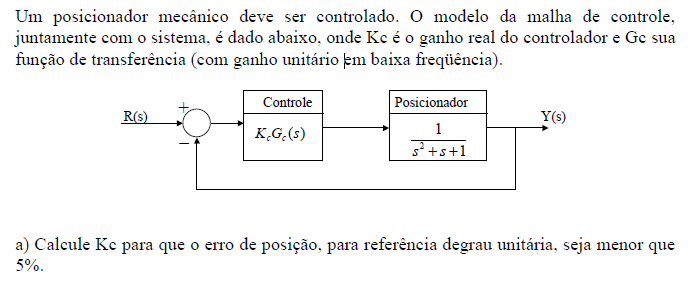

clear;clc;close all;

Erro ao degrau


$$K_p=\lim_{s\rightarrow0}K_cG(s)=\lim_{s\rightarrow0}\frac{K_c}{s^2+s+1}=K_c$$



$$e(\infty)=\frac{1}{1+K_p}=0.05$$


Kc=(1-0.05)/0.05

Kc = 19.0000


$$K_c\geq19$$


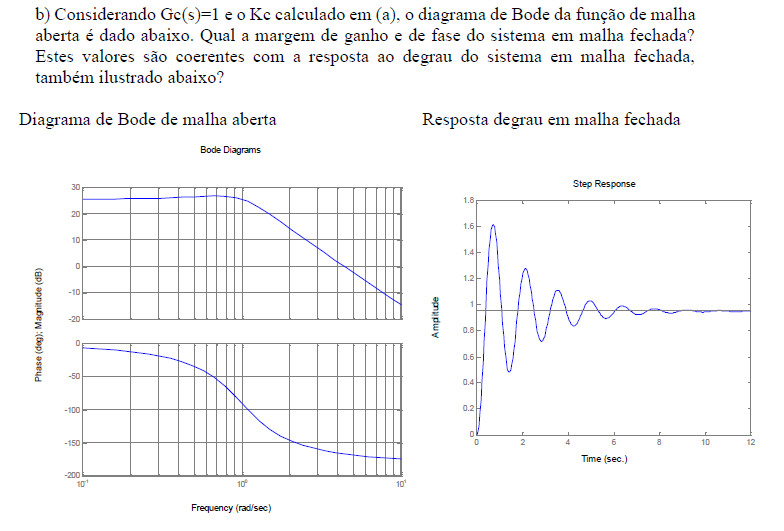

Análise do gráfico:

Olhando pelo gráfico, a margem de ganho será infinita, pois o gráfico da fase nunca chega em -180º e a margem de fase será $\pm$ uns 10º (180º+fase onde o módulo é 0 dB)

Cálculo analítico:

syms omega
Gjw=Kc/((j*omega)^2+(j*omega)+1)

$$Gjw = \frac{19}{-\omega^{2}+\omega \,\mathrm{i}+1}$$

% Calculanmdo a margem de fase apenas, pois claramente a margem de ganho é
% infinita
wc=double(solve(19==sqrt((-omega^2+1)^2+omega^2),omega))

wc =    0.0000 - 4.2989i
   0.0000 + 4.2989i
  -4.4136 + 0.0000i
   4.4136 + 0.0000i


wc=wc(4) % pegando o unico valor positivo e real

wc = 4.4136

MF=180+rad2deg(angle(Kc/((j*wc)^2+(j*wc)+1)))

MF = 13.4323

Cálculo pela função margin:

s=tf([1 0],1);
G=1/(s^2+s+1);
[MG,MF]=margin(Kc*G);
fprintf('A margem de ganho é %f dB e a margem de fase %2.2f graus',MG,MF)

A margem de ganho é Inf dB e a margem de fase 13.43 º

Antes de plotar o diagrama vamos analisar a FT de malha aberta $K_cG(s)=\frac{K_c}{s^2+s+1}$

A FT é de ordem 2, tipo 0 e não possui nenhum zero.

O diagrama ira começar com fase 0º e ganmho igual a $K_c$ e irá terminar com ganho 0dB e fase -180º.

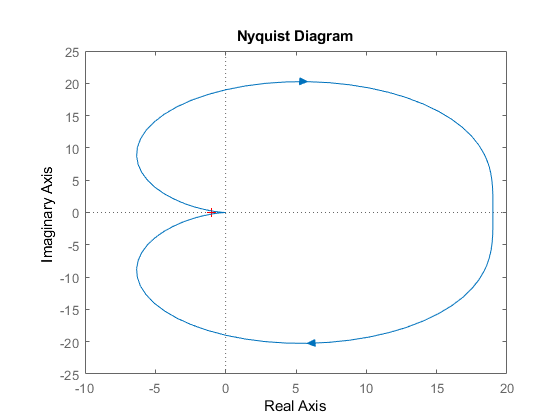

nyquist(Kc*G)

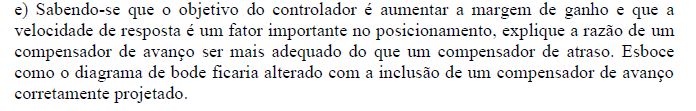

O compensador de avanço tem esse nome pois aumenta o ganho em alta frequência e com isso desloca a frequência de corte da margem de fase para a direita, deixando o sistema mais rápido. Não irei esboçar o diagrama de Bode agora pois irei plotá-lo no próximo item.

phi=50-MF+5 % 5 graus de gordura

phi = 41.5677

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.2023

modulo=-20*log10(1/sqrt(alfa)) %em dB

modulo = -6.9404

[mag,phase,wout] = bode(Kc*G);
wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 6.5374

T=1/(sqrt(alfa)*wc)

T = 0.3401

Gc=Kc*(1+s*T)/(1+alfa*s*T)

Gc =
 
  6.462 s + 19
  ------------
  0.0688 s + 1
 
Continuous-time transfer function.



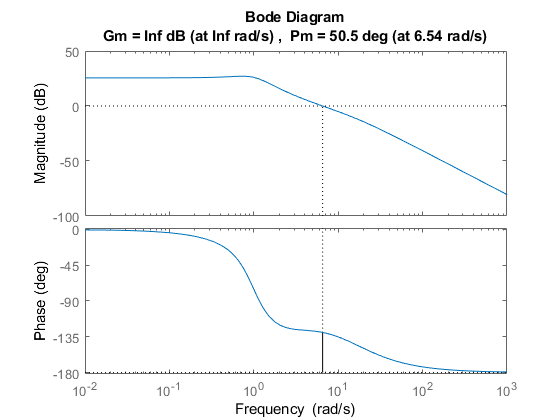

margin(Gc*G)

## pg 20

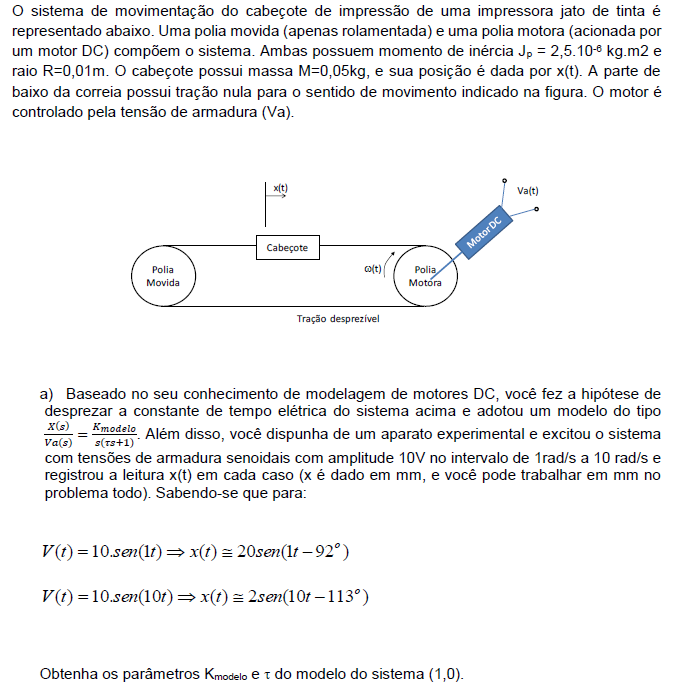

clear;clc;close all;

Olhando para a amplificação em baixa frequência (1rad/s) vemos ques $K_{modelo}=\frac{20}{10}=2$

Então, $G(s)=\frac{10}{s(\tau s +1)}\rightarrow G(j\omega)=\frac{10}{-\tau \omega^2  + j\omega}=\frac{10(-\tau\omega^2-j\omega)}{(-\tau \omega^2)^2  + \omega^2}$


$$\angle{G(j\omega)}=tg^-1\frac{1}{\tau \omega}$$


Olhando agora pra alta frequência (10rad/s) vemos que a fase é -113º


$$\frac{1}{10\tau}=tg(-113º)$$


K=2;
tao=1/(10*tand(-113))

tao = 0.0424

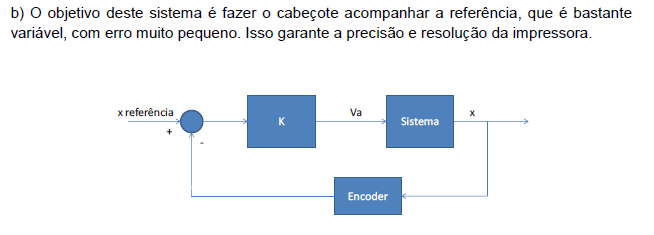

Erro à rampa


$$K_v=\lim_{s\rightarrow0}sK_cG(s)=K_cK$$



$$e(\infty)=\frac{1}{K_v}$$


e=1-0.99

e = 0.0100

Kv=1/e

Kv = 100.0000

Kc=Kv/K

Kc = 50.0000

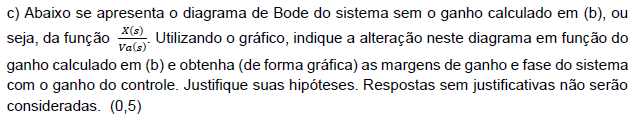

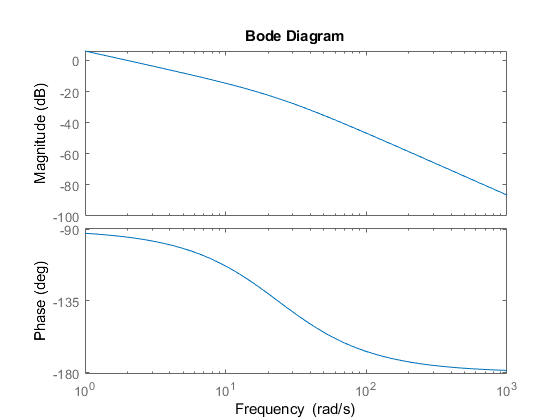

% plotando para ter uma resolução melhor que a da figura do pdf
s=tf([1 0],1);
G=K/(s*(tao*s+1));
bode(G)

ganho=20*log10(Kc)

ganho = 33.9794

A nova frequencia de corte da margem de fase será aquela em que o ganho no diagrama de G pura é -33dB. A margem de ganho é infinita pois o gráfico de fase nunca chega em -180º.

% pegando valores no gráfico
MF=180-151.9;
fprintf('Margem de fase %3.2f graus',MF)

Margem de fase 28.10 graus

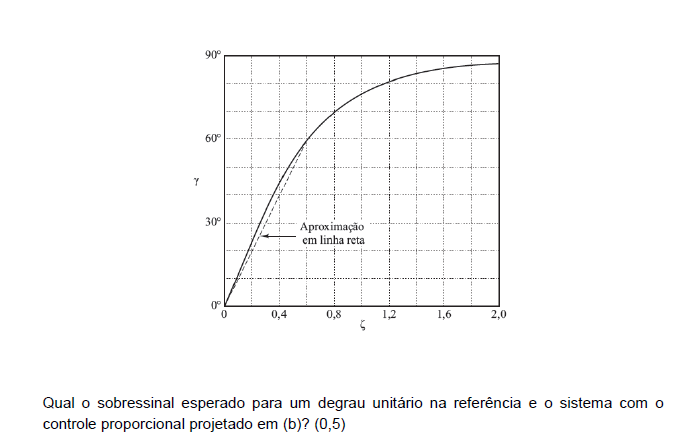

m=(40/0.4) % coeficiente angular da aproximação linear

m = 100

z=MF/m % amortecimento calculado pela reta

z = 0.2810

Mp=exp(-z*pi/sqrt(1-z^2));
fprintf('Sobressinal de %3.2f %%',100*Mp)

Sobressinal de 39.86 %

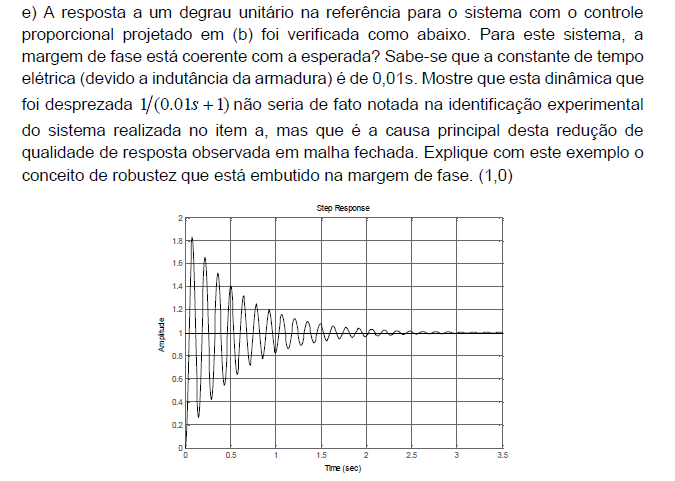

Não está coerente, pois o sobressinal no gráfico é de mais de 80% e o esperado era de apenas 40%. 

Vamos analisar a dinâmica desprezada para a maior frequência do teste (10rad/s)

w=10;
modulo=abs(1/(0.01*j*w+1))

modulo = 0.9950

fase=rad2deg(angle(1/(0.01*j*w+1)))

fase = -5.7106

Para a maior frequência dos testes realizados a atenuação causada por essa dinâmica é de apenas 0.5% e o desvio de fase de -5.71º, valores quase imperceptíveis no teste.

Porém, como podemos observar no diagrama de bode do item c), a frequencia de corte da margem de fase com o ganho $K_c$ é de 44 rad/s. Vamos analisar a dinâmica para essa frequência. 

w=44;
modulo=abs(1/(0.01*j*w+1))

modulo = 0.9153

fase=rad2deg(angle(1/(0.01*j*w+1)))

fase = -23.7495

Temos uma atenuação de quase 10% e um desvio de fase de -24º, valores consideráveis. A margem de fase será reduzida para apenas 4º e o sobressinal será 

z=4/m % amortecimento calculado pela reta

z = 0.0400

Mp=exp(-z*pi/sqrt(1-z^2));
fprintf('Sobressinal de %3.2f %%',100*Mp)

Sobressinal de 88.18 %

o que explica a resposta ao degrau apresentada no gráfico.

Logo, a margem de fase está diretamente ligada com o sobressinal e consequentemente com a robustez do controlador.

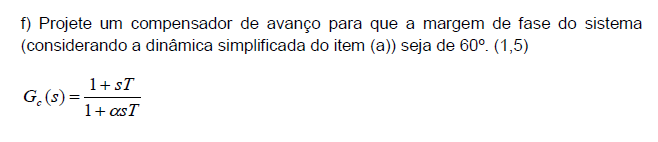

phi=60-MF+5 % 5 graus de gordura

phi = 36.9000

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.2497

modulo=-20*log10(1/sqrt(alfa)) %em dB

modulo = -6.0263

[mag,phase,wout] = bode(Kc*G);
wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 66.8381

T=1/(sqrt(alfa)*wc)

T = 0.0299

Gc=Kc*(1+s*T)/(1+alfa*s*T)

Gc =
 
   1.497 s + 50
  --------------
  0.007476 s + 1
 
Continuous-time transfer function.



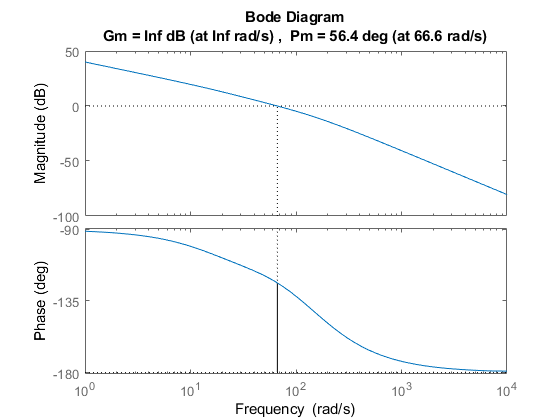

margin(Gc*G)

## pg 30

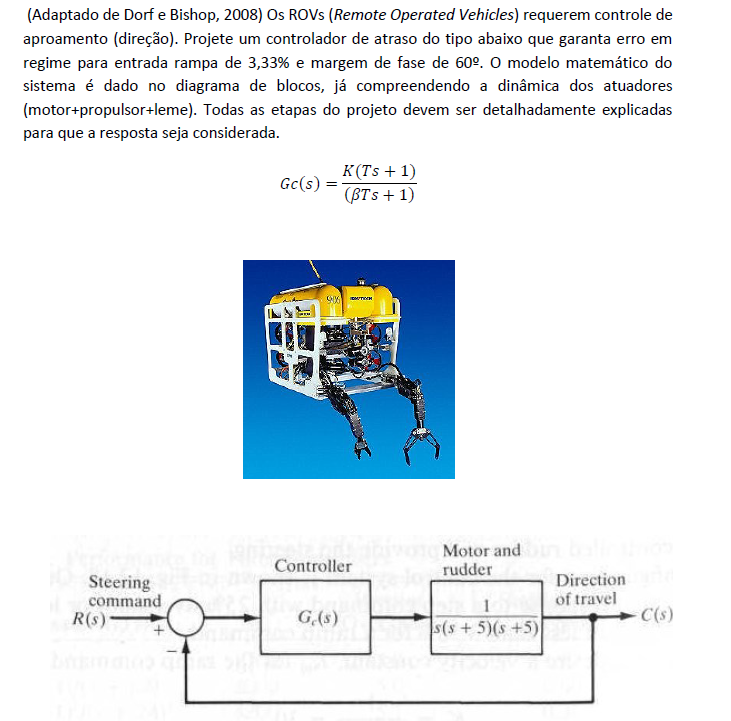

clear; clc; close all;
s=tf('s');
G=1/(s*(s+5)*(s+5))

G =
 
           1
  -------------------
  s^3 + 10 s^2 + 25 s
 
Continuous-time transfer function.



Kv=1/0.0333

Kv = 30.0300

Kc=Kv*5*5  % limite de s*Kc*G quando s tende a zero

Kc = 750.7508

[Gm,Pm,Wcg,Wcp] = margin(Kc*G)

Gm = 0.3330

Pm = -27.0993

Wcg = 5

Wcp = 8.1751

fase=-(180-60)+10

fase = -110

[mag,phase,wout] = bode(Kc*G);
wc=interp1(phase(:),wout,fase)

wc = 0.8817

modulo=interp1(wout,20*log10(mag(:)),wc)

modulo = 30.3873

beta=10^(modulo/20)

beta = 33.0648

T=10/wc

T = 11.3419

Gc=Kc*(1+T*s)/(1+T*beta*s)

Gc =
 
  8515 s + 750.8
  --------------
    375 s + 1
 
Continuous-time transfer function.



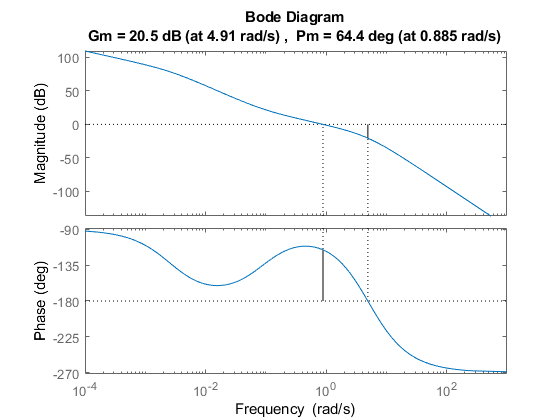

margin(Gc*G)

sys=feedback(G*Gc,1);
t=linspace(0,15,100);
r= step(1/s,t); % entrada rampa
y = step(sys/s,t); % resposta a rampa
erro=(r(end)-y(end))/r(end);
fprintf('erro de %2.2f%%',erro*100)

erro de 2.19%

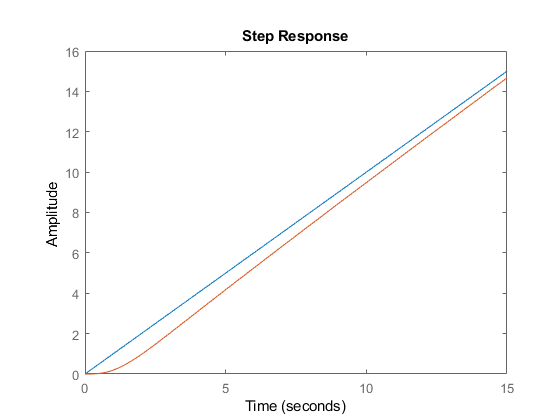

step(1/s,t) % entrada rampa
hold on
step(sys/s,t) % resposta a rampa
hold off

## pg 32

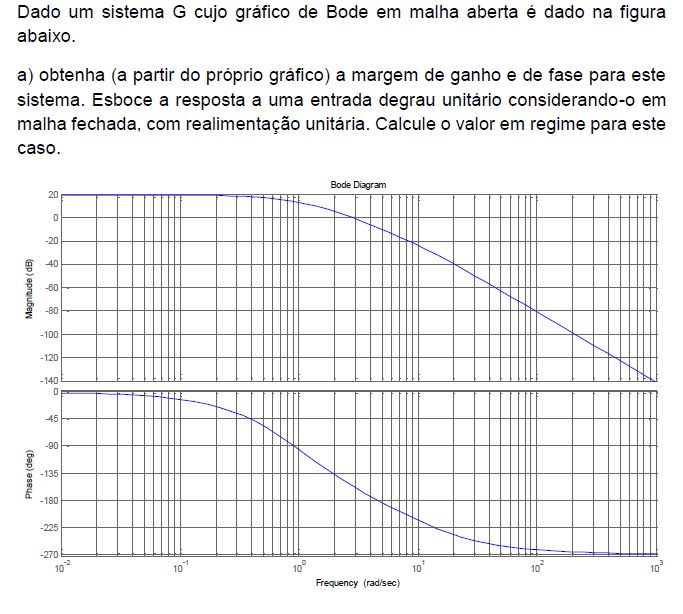

Pelo gráfico, $MG=8dB$ e $MF=180º-157.5º=22.5º$

O sistema acima parece ser de terceira ordem com 3 polos iguais, pois cai 60dB/dec e não é possível distinguir três quedas de 20dB/dec separadas. Vamos tentar estimá-lo para prosseguir com a questão usando o MATLAB e verificar o resultado obtido pelo gráfico.

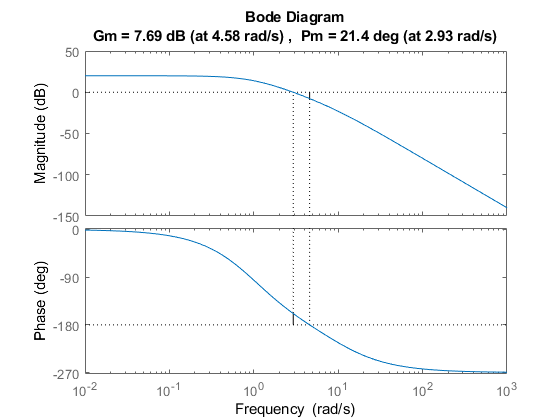

clear;clc;close all;
w=logspace(-2,3,100);
s=tf('s');
T1=1/1; % 1/frequência na qual o ganho é 20dB-6dB=14dB
T2=1/10; % 1/frequência na qual a inclinação da reta muda para -60dB/dec
K=10^(20/20); % ganho de 20dB em baixa frequência
G=K/(T1*s+1)/(T1*s+1)/(T2*s+1);
[mag,phase,wout] = bode(G,w);
margin(mag,phase,w)

Esse diagrama de bode é bem próximo daquele dado pela questão. Então podemos considerar para os próximos itens que  $G(s)\approx\frac{10}{(s+1)^2(0.1s+1)}$

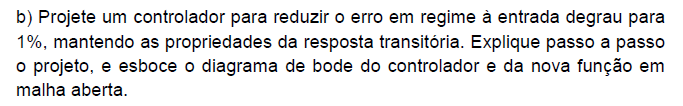

Erro ao degrau


$$K_p=\lim_{s\rightarrow0}K_cG(s)=10K_c$$



$$e(\infty)=\frac{1}{1+K_p}=0.01$$


Kp=(1-0.01)/0.01

Kp = 99

Kc=Kp/10

Kc = 9.9000

Para manter as propriedades da resposta transitória podemos usar um compensador de atraso

[Gm,Pm,Wcg,Wcp] = margin(Kc*G)

Gm = 0.2444

Pm = -27.4536

Wcg = 4.5826

Wcp = 8.6048

fase=-(180-21.4)+5 % Mesma margem de fase sem o ganho Kc

fase = -153.6000

[mag,phase,wout] = bode(Kc*G);
wc=interp1(phase(:),wout,fase)

wc = 2.6655

modulo=interp1(wout,20*log10(mag(:)),wc)

modulo = 21.4718

beta=10^(modulo/20)

beta = 11.8465

T=10/wc

T = 3.7516

Gc=Kc*(1+T*s)/(1+T*beta*s)

Gc =
 
  37.14 s + 9.9
  -------------
   44.44 s + 1
 
Continuous-time transfer function.



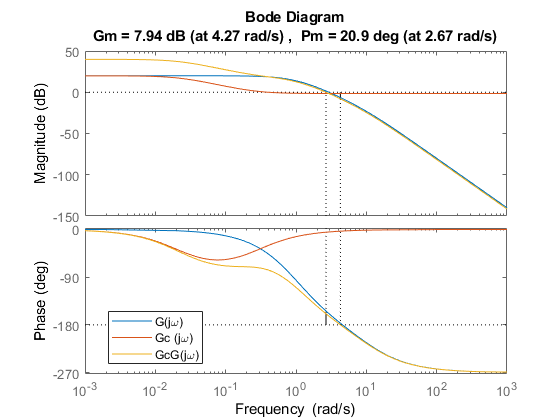

bode(G)
hold on
bode(Gc)
margin(Gc*G)
hold off
legend('G(j\omega)','Gc (j\omega)','GcG(j\omega)','Location',"best")

Percebemos um aumento do ganho em baixa frequência praticamente sem alterações nas margens. Como uma entrada degrau é uma entrada com frequência zero, esse ganho em baixa frequência irá atenuar significativamente o erro em regime.

Podemos testar isso simulando uma entrada degrau.

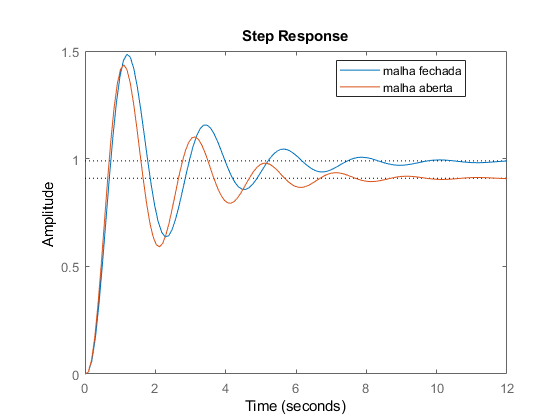

sys_mf=feedback(Gc*G,1);
sys_ma=feedback(G,1);
step(sys_mf)
hold on
step(sys_ma)
legend('malha fechada','malha aberta','Location',"best")

## pg 38

Apenas o item d)

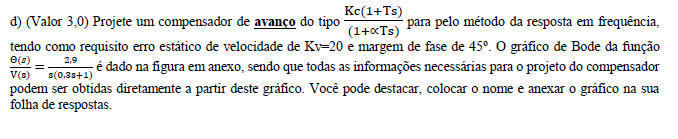

FT: $G(s)=\frac{2.9}{s(0.3s+1)}$ Requsitos: $MF=45º$ e $K_V=20$

clear;clc;close all;
Kv=20;
Kc=20/2.9

Kc = 6.8966

s=tf('s');
G=2.9/(s*(0.3*s+1));
[MG,MF,Wcg,Wcp] = margin(Kc*G)

MG = Inf

MF = 23.0552

Wcg = Inf

Wcp = 7.8319

phi=45-MF+5

phi = 26.9448

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.3763

[mag,phase,wout] = bode(Kc*G);
modulo=-20*log10(1/sqrt(alfa))

modulo = -4.2442

wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 10.1723

T=1/(wc*sqrt(alfa))

T = 0.1602

Gc=Kc*(1+s*T)/(1+s*alfa*T)

Gc =
 
  1.105 s + 6.897
  ---------------
   0.06031 s + 1
 
Continuous-time transfer function.



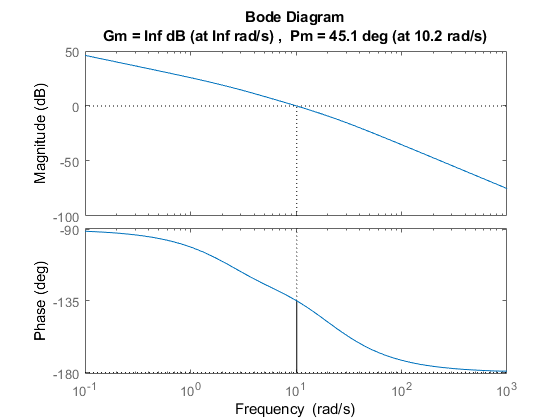

margin(Gc*G)

t=linspace(0,60,100);
sys_mf=feedback(G*Gc,1);
y=step(sys_mf/s,t);
r=step(1/s,t);
erro=r(end)-y(end);
Kv=1/erro

Kv = 20.0000

## pg 43

clear; clc; close all
Kv0=0.5; % 0.5/(0^2+2*0+1)
e0=1/Kv0 % erro sem controlador

e0 = 2

e=e0/5 % erro desejado

e = 0.4000

Kv=1/e % Kv desejado

Kv = 2.5000

Kc=Kv/0.5 % ganho do controlador

Kc = 5

s=tf('s');
G=0.5/(s*(s^2+2*s+1))

G =
 
        0.5
  ---------------
  s^3 + 2 s^2 + s
 
Continuous-time transfer function.



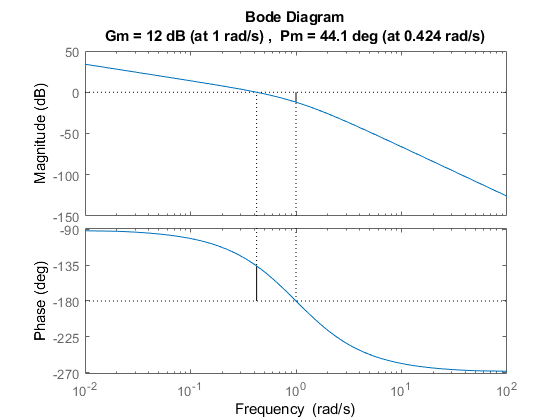

margin(G)

Se queremos manter a margem de ganho, não podemos alterar o diagrama para médias e altas frequências. Para que o compensador de avanço não tenho ganho em alta freqência, precisamos fazer $\beta=K_c$ e para que não altere a fase, $\frac{1}{T}\leq\frac{0.4}{10}$ (uma década abaixo da frequência de corte da margem de fase).

beta=Kc

beta = 5

T=10/0.4

T = 25

Gc=Kc*(1+T*s)/(1+T*beta*s)

Gc =
 
  125 s + 5
  ---------
  125 s + 1
 
Continuous-time transfer function.



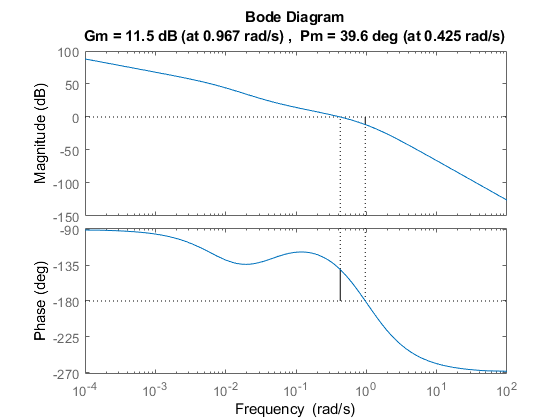

margin(G*Gc)

Podemos ver que as margens de ganho e fase foram pouco afetadas. Um resultado um pouco melhor poderia ser obtido com T um pouco maior, pois isso deslocaria o "calombo" causado pelo compensador de atraso mais para a esquerda, afetrando menos os pontos onde estão as margens.

Verificando o erro com controlador

t=linspace(0,100,200);
sys1=feedback(G,1);
y1 = step(sys1/s,t); % sem controlador
sys2=feedback(Gc*G,1);
y2 = step(sys2/s,t); % com controlador
r = step(1/s,t); % entrada rampa
e1=r(end)-y1(end)

e1 = 2.0000

e2=r(end)-y2(end)

e2 = 0.4241

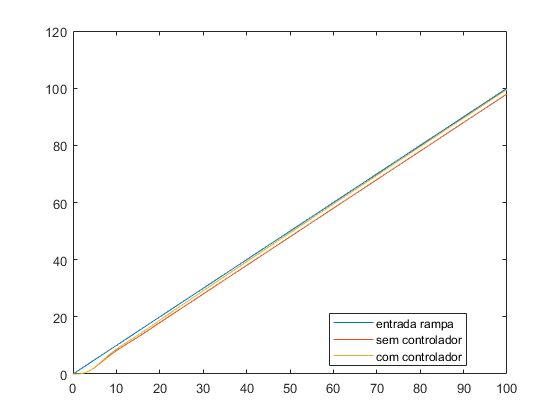

plot(t,r)
hold on
plot(t,y1)
plot(t,y2)
hold off
legend('entrada rampa','sem controlador','com controlador','Location',"best")

## pg 45

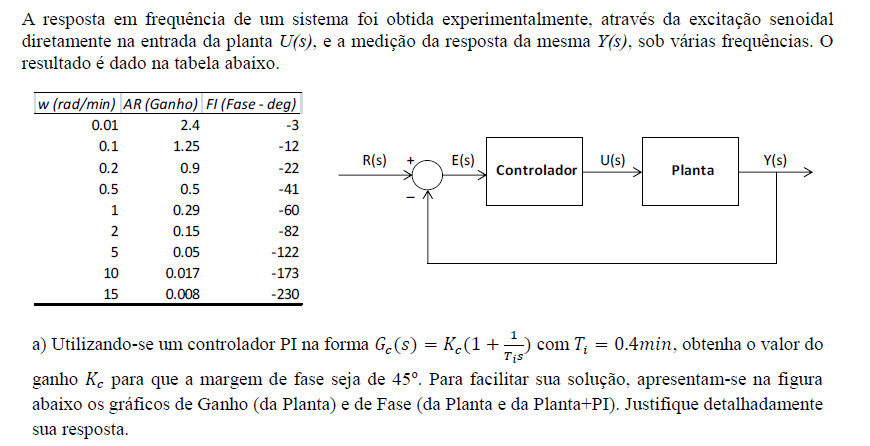

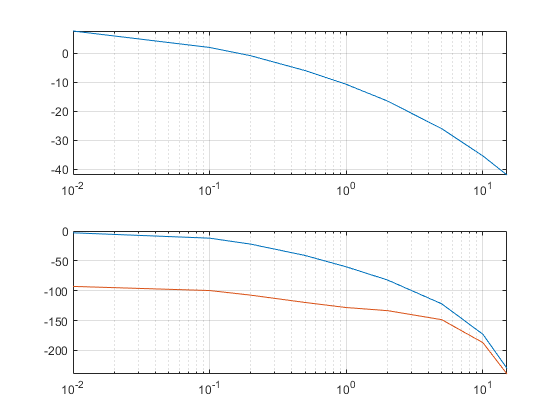

clear; close all; clc;
wout=[0.01,0.1,0.2,0.5,1,2,5,10,15];
mag=[2.4,1.25,0.9,0.5,0.29,0.15,0.05,0.017,0.008];
magdB=20.*log10(mag);
fase=[-3,-12,-22,-41,-60,-82,-122,-173,-230];
s=tf('s');
Gc=1+1/(0.4*s);
[mc,pc,woutc] = bode(Gc,wout);
subplot(2,1,1);
semilogx(wout,magdB)
grid on
subplot(2,1,2);
semilogx(wout,fase)
hold on
semilogx(wout,fase+pc(:)')
grid on
hold off

podemos ver pelo gráfico em  vermelho que a frequência de corte na qual a margem de fase seria 45º (fase=-135) é 2 rad/s. Para que essa realmente seja a frequencia de corte da margem de fase, o módulo do ganho para essa frequência tem que ser 1 (0dB).

O ganho para o sistema sem controlador nessa frequência é -16.48dB

ganho=10^(-16.48/20)

ganho = 0.1500

O compensador deve aumentar esse ganho para 1


$$G_c(j\omega)=K_C(1+\frac{1}{0.4j\omega})$$


Kc=1/0.15/abs(1+1/(0.4*j*2))

Kc = 4.1646

Como podemos ver no gráfico dado, a fase com o controlador PI é -180º para a frequência de  8.8rad/s

A margem de ganho pode ser calculada como o inverso do ganho nessa frequência.

w=8.8;
ganho_planta=10^(-34/20) % -34dB

ganho_planta = 0.0200

ganho=ganho_planta*Kc*abs(1+1/(0.4*j*w))

ganho = 0.0864

MG=1/ganho

MG = 11.5763

MGdb=20*log10(MG)

MGdb = 21.2714

## pg 47

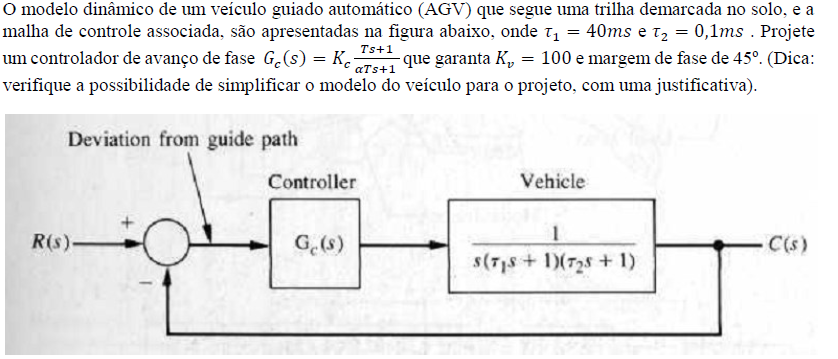


$$G(s)=\frac{1}{s(40s+1)(0.1s+1)}$$


clear; close all; clc;
s=tf('s');
G=1/(s*(40*s+1)*(0.1*s+1));
damp(G)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -2.50e-02     1.00e+00       2.50e-02         4.00e+01    
 -1.00e+01     1.00e+00       1.00e+01         1.00e-01    


O sistema tem 3 pólos, em  0, -0.025 e -10. O pólo em -10 é não dominante por ser muito mais rápido e pode ser desprezado.


$$G(s)\approx\frac{1}{s(40s+1)}$$



$$K_v=\lim_{s\rightarrow0}sK_cG(s)=100$$


Kc=100;
[Gm,Pm,Wcg,Wcp] = margin(Kc*G)

Gm = 0.1002

Pm = -8.0165

Wcg = 0.5000

Wcp = 1.5710

phi=45-Pm+10

phi = 63.0165

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.0576

modulo=-20*log10(1/sqrt(alfa))

modulo = -12.3984

[mag,phase,wout] = bode(Kc*G);
wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 3.1606

T=1/(sqrt(alfa)*wc)

T = 1.3187

Gc=Kc*(1+T*s)/(1+alfa*T*s)

Gc =
 
  131.9 s + 100
  -------------
  0.07591 s + 1
 
Continuous-time transfer function.



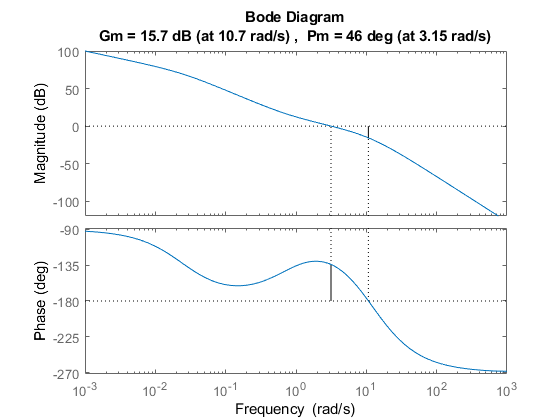

margin(Gc*G)

## pg 50

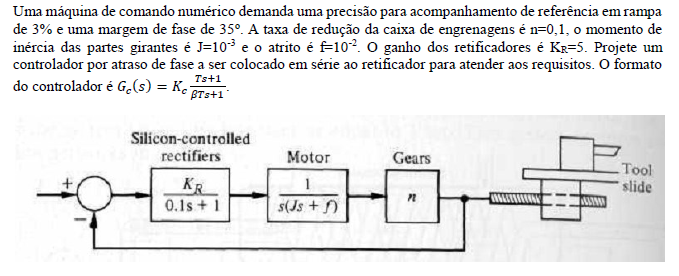

$G(s)=\frac{0.5}{s(0.1s+1)(0.001s+0.01)}$ Compensador de atraso para $K_v=\frac{1}{0.03}$ e $MF=35º$

s=tf('s');
G=0.5/(s*(0.1*s+1)*(0.001*s+0.01));
Kv=1/0.03

Kv = 33.3333

Kc=Kv/0.5*0.01

Kc = 0.6667

[Gm,Pm,Wcg,Wcp] = margin(Kc*G)

Gm = 0.6000

Pm = -13.6780

Wcg = 10.0000

Wcp = 12.7256

fase=-(180-35)+10

fase = -135

[mag,phase,wout] = bode(Kc*G);
wc=interp1(phase(:),wout,fase)

wc = 4.1457

modulo=interp1(wout,20*log10(mag(:)),wc)

modulo = 16.7475

beta=10^(modulo/20)

beta = 6.8766

T=10/wc

T = 2.4121

Gc=Kc*(1+s*T)/(1+s*beta*T)

Gc =
 
  1.608 s + 0.6667
  ----------------
    16.59 s + 1
 
Continuous-time transfer function.



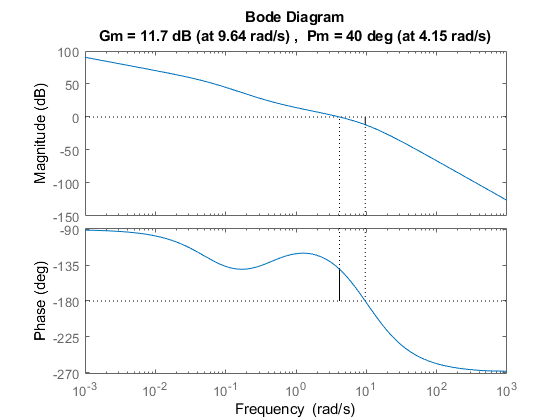

margin(G*Gc)

t=linspace(0,50,100);
sys=feedback(Gc*G,1);
y=step(sys/s,t);
r=step(1/s,t);
Kv=1/(r(end)-y(end))

Kv = 33.3333

## pg 51

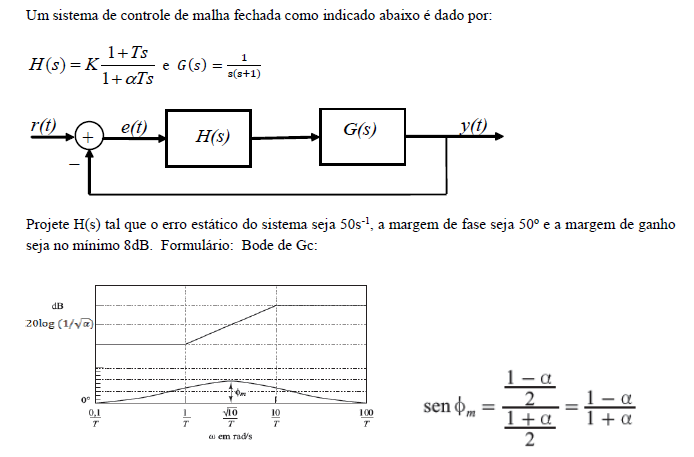

Compensador de avanço para $Kv=50$ e $MF=50º$

Kv=50;
Kc=Kv

Kc = 50

s=tf('s');
G=1/(s*(s+1));
[Gm,Pm,Wcg,Wcp] = margin(Kc*G)

Gm = Inf

Pm = 8.0895

Wcg = Inf

Wcp = 7.0356

phi=50-Pm+10

phi = 51.9105

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.1192

[mag,phase,wout] = bode(Kc*G);
modulo=-20*log10(1/sqrt(alfa))

modulo = -9.2385

wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 12.0283

T=1/(sqrt(alfa)*wc)

T = 0.2408

Gc=Kc*(1+T*s)/(1+T*s*alfa)

Gc =
 
  12.04 s + 50
  ------------
  0.0287 s + 1
 
Continuous-time transfer function.



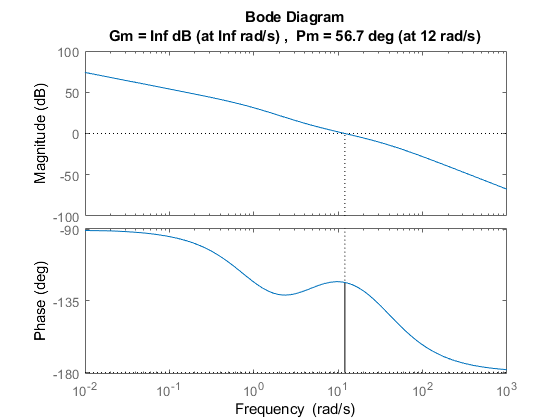

margin(G*Gc)

sys=feedback(G*Gc,1);
t=linspace(0,50,100);
y=step(sys/s,t);
r=step(1/s,t);
Kv=1/(r(end)-y(end))

Kv = 50.0000

## pg 59

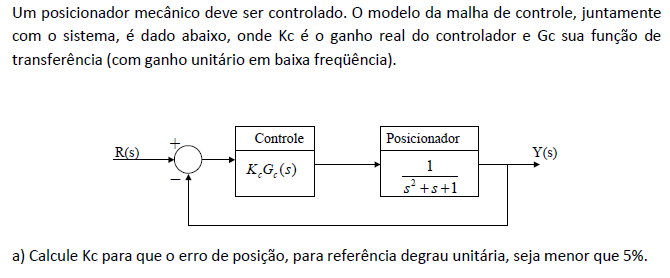


$$K_p=\lim_{s\rightarrow0}K_cG(s)=K_c$$



$$e(\infty)=\frac{1}{1+K_p}=\frac{1}{1+K_c}=0.05$$


clear;clc;close all;
Kc=(1-0.05)/0.05

Kc = 19.0000

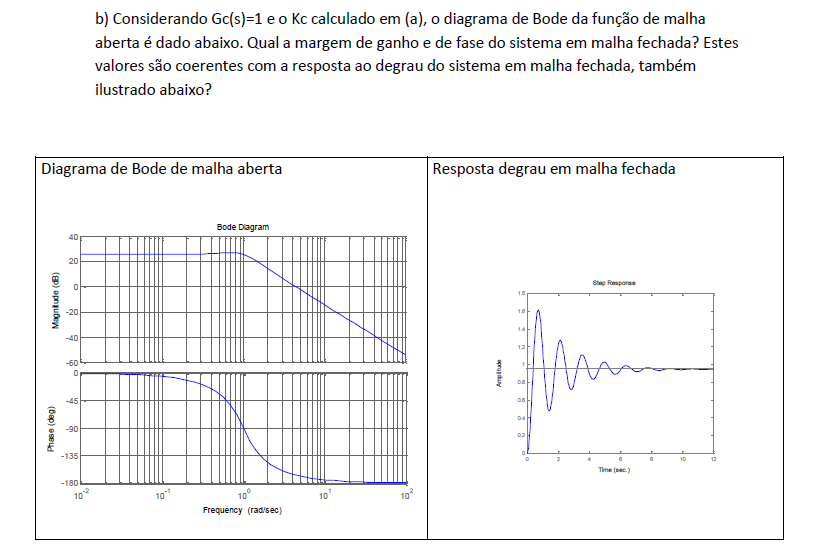

A margem de ganho é infinita porque a fase nunca chega a -180º e a margem de fase é 180º-166.5º=13.5º. A resposta degrau é coerente, pois a MF é pequena e isso implica em sobressinal alto.

s=tf('s');
G=1/(s^2+s+1);
[MG,MF]=margin(Kc*G)

MG = Inf

MF = 13.4323

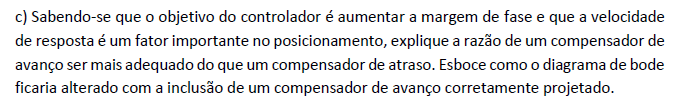

O compensador de avanço leva a frequência de corte da margem de fase para a direita, deixando o sistema mais rápido.

phi=50-MF+10

phi = 46.5677

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.1586

[mag,phase,wout] = bode(Kc*G);
modulo=-20*log10(1/sqrt(alfa))

modulo = -7.9963

wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 6.9632

T=1/(sqrt(alfa)*wc)

T = 0.3606

Gc=Kc*(1+T*s)/(1+T*s*alfa)

Gc =
 
  6.851 s + 19
  ------------
  0.0572 s + 1
 
Continuous-time transfer function.



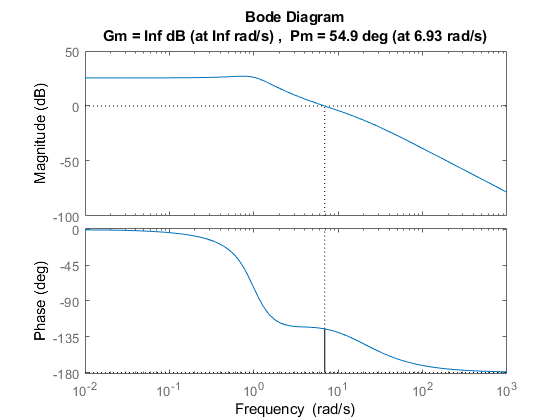

margin(G*Gc)

sys=feedback(G*Gc,1);
t=linspace(0,50,100);
y=step(sys/s,t);
r=step(1/s,t);
erro=(r(end)-y(end))/r(end)*100

erro = 5.0662

## pg 68

clear;clc;close all;
s=tf('s');
G=(s+1)*(s+2)/(s^2*(s+3)*(s^2+2*s+25));
[MG,MF]=margin(G)

MG = 52.3529

MF = 10.1581

Kmg=10^((20*log10(MG)-3)/20) % MG-20*log10(K)=3

Kmg = 37.0630

fase=30-180 % fase no wc em que MF é 30º

fase = -150

[mag,phase,wout] = bode(G);
modulo=interp1(phase(:),20*log10(mag(:)),fase) % modulo no wc em que MF é 30º

modulo = -20.7211

Kmf=10^(-modulo/20) % K tem que reduzir esse modulo para 0dB

Kmf = 10.8657


$$10.8\leq K\leq 37$$


Kmax=MG

Kmax = 52.3529

## pg 103

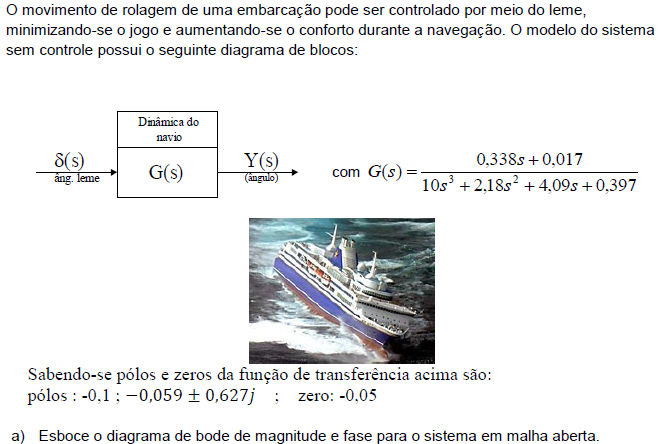

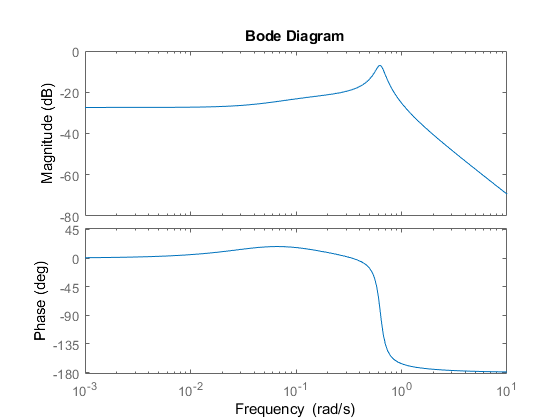

clear; clc; close all;
s=tf('s');
G=(0.338*s+0.017)/(10*s^3+2.18*s^2+4.09*s+0.397);
bode(G)

Para baixa freqência, o navio apresentará um angulo de rolagem, pois o ganho para $\omega=0$ é de quase -30dB. Para cada grau de leme constante, ele apresentará $10^{\frac{-30}{20}}=0.032º$ de rolagem.

Para 0.9rad/s o diagrama de módulo possui um pico, o que significa que a saída (rolagem) será considerável para essa frequência.

## pg 118

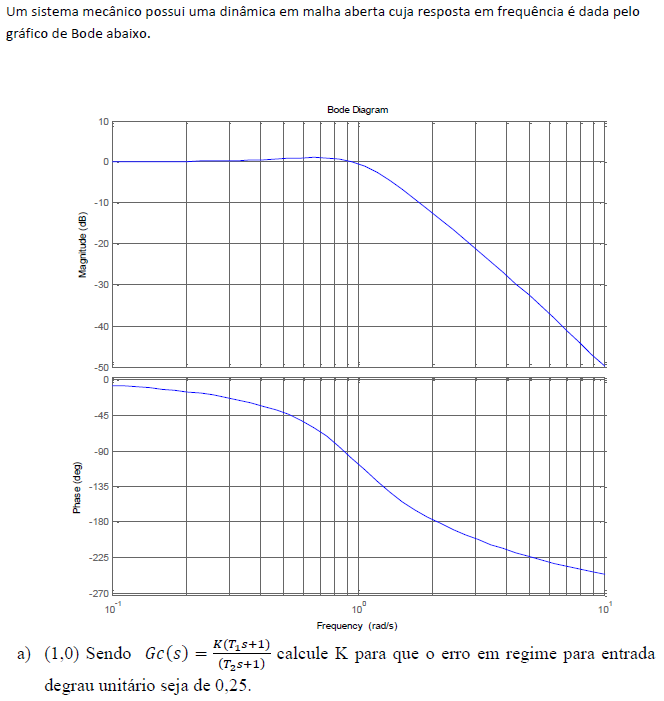

Erro ao degrau


$$K_p=\lim_{s\rightarrow0}G_c(s)G(s)=K_c$$



$$e(\infty)=\frac{1}{1+K_p}=0.25$$


Kc=(1-0.25)/0.25

Kc = 3

% MF de Kc*G
ganho=20*log10(Kc)

ganho = 9.5424

A nova margem de fase será então na frequência em que o módulo é -9.54dB

fase=-165; % do gráfico
MF=15; % do gráfico
phi=30-15+10

phi = 25

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.4059

modulo=-20*log10(1/sqrt(alfa))

modulo = -3.9163

wc=2.2; % do gráfico
T=1/(sqrt(alfa)*wc)

T = 0.7135

Gc=Kc*(1+T*s)/(1+T*s*alfa)

Gc =
 
   2.14 s + 3
  ------------
  0.2896 s + 1
 
Continuous-time transfer function.



fase=-180+30+10

fase = -140

wc=1.4; % do gráfico
ganho=5; % do gráfico
beta=10^(ganho/20)

beta = 1.7783

T=5/wc; %n sei pq nessa o prof n usa 10 no gabarito 
Gc=Kc*(1+s*T)/(1+s*beta*T)

Gc =
 
  10.71 s + 3
  -----------
  6.351 s + 1
 
Continuous-time transfer function.



## pg 125

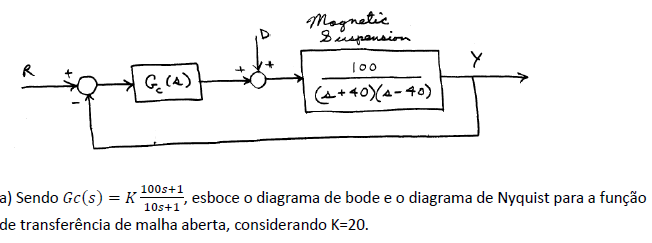

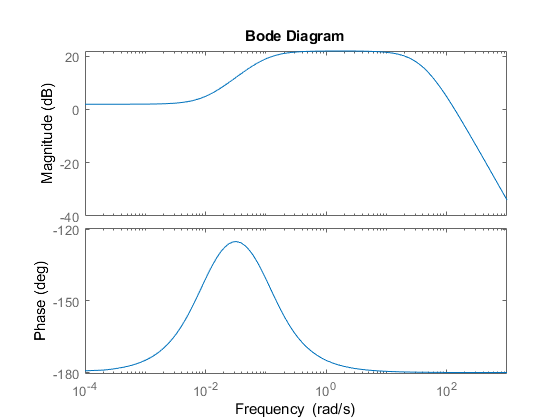

s=tf('s');
G=100/(s-40)/(s+40);
Gc=20*(100*s+1)/(10*s+1);
bode(Gc*G)

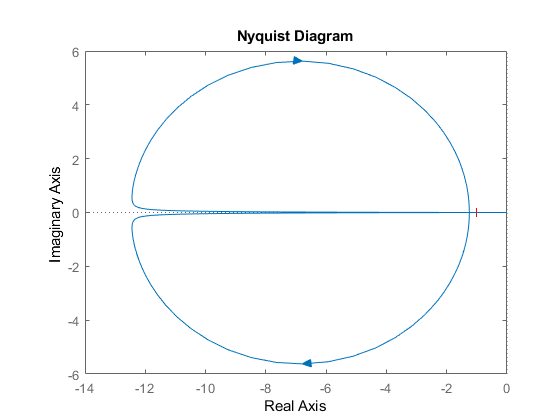

nyquist(Gc*G)

O sistema em malha aberta tem um pólo no SPD

Para estabilidade, Z=P+N=1+N=0, N=-1. O diagrama de Nyquist tem que dar uma volta no sentido anti-horário ao redor do ponto -1 do eixo real para que a resposta em malha fechada seja estável.

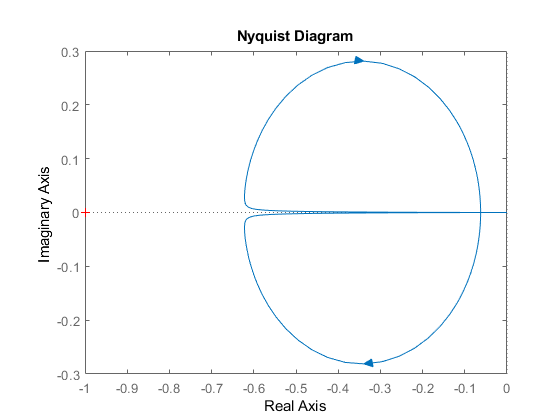

nyquist(Gc*G/20)

Plotando o diagrama de Nyquist para K=1 temos que o diagrama cruza o eixo real em -0.0625 e a direita desse ponto o diagrama dá uma volta no sentido anti-horário. O valor mínimo de K para a estabilidade será aquele que levar esse ponto para -1.

Kmin=1/0.0625

Kmin = 16

## pg 127

Só o item b)

Erro à rampa


$$K_v=\lim_{s\rightarrow0}sK_cG(s)$$


clear;close all;clc;
Kc=10/40*20

Kc = 5

s=tf('s');
G=40/(60*s^2+20*s);
[MG,MF]=margin(Kc*G)

MG = Inf

MF = 10.4318

phi=40-MF+10

phi = 39.5682

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.2217

[mag,phase,wout] = bode(Kc*G);
modulo=-20*log10(1/sqrt(alfa))

modulo = -6.5414

wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 2.6563

T=1/(sqrt(alfa)*wc)

T = 0.7995

Gc=Kc*(1+T*s)/(1+T*s*alfa)

Gc =
 
  3.997 s + 5
  ------------
  0.1773 s + 1
 
Continuous-time transfer function.



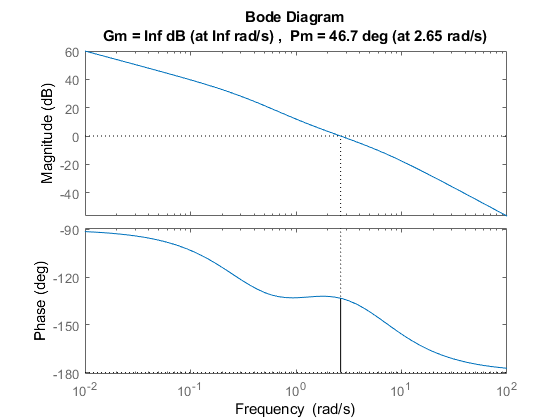

margin(G*Gc)

sys=feedback(G*Gc,1);
t=linspace(0,10,100);
y=step(sys/s,t);
r=step(1/s,t);
erro=(r(end)-y(end))

erro = 0.1000

Kv=1/erro

Kv = 10.0000

## pg 148

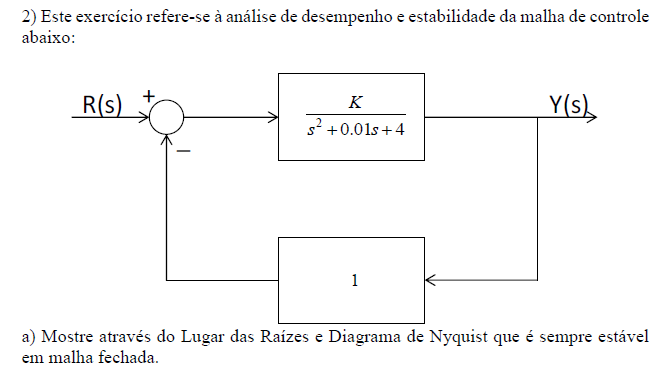

Lugar das raízes não é matéria dessa prova, mas é só um comando no matlab.

s=tf('s');
G=1/(s^2+0.01*s+4)

G =
 
         1
  ----------------
  s^2 + 0.01 s + 4
 
Continuous-time transfer function.



damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.00e-03 + 2.00e+00i     2.50e-03       2.00e+00         2.00e+02    
 -5.00e-03 - 2.00e+00i     2.50e-03       2.00e+00         2.00e+02    


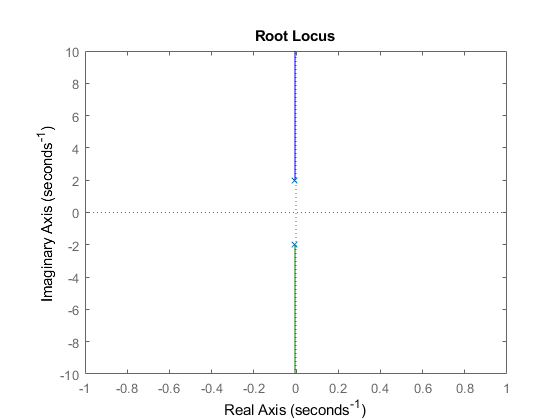

rlocus(G)

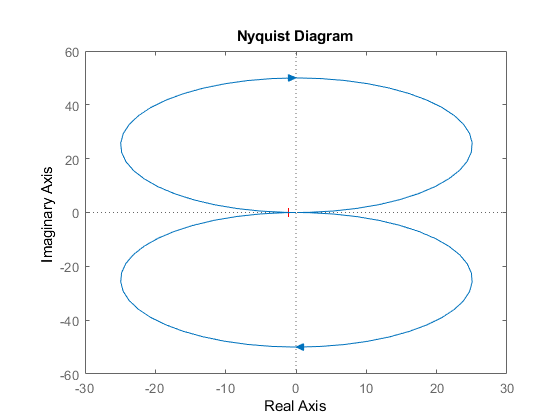

nyquist(G)

Pelo lugar das raízes, vemos que ele nunca cruza o eixo imaginário, então para qualquer valor de K não há polos no SPD.

Pelo diagrama de Nyquist vemos que ele nunca cruza o eixo real, então para qualquer valor de K, N será zero. Como o sistema em malha aberta não tem polos no SPD, a condição de estabilidade é N=-P=0. Logo, ele será estável para qualquer valor de K.

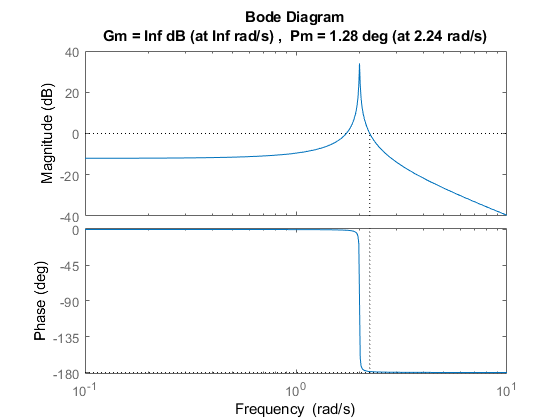

margin(G)

O sistema tem uma margem de fase bem baixa para K=1. Ainda que estável, para esse valor de K ele apresentará um comportamento bem oscilatório. A margem de fase irá decrescer com o valor de K, então quanto maior o valor de K, mais oscilatória a resposta ao degrau será.

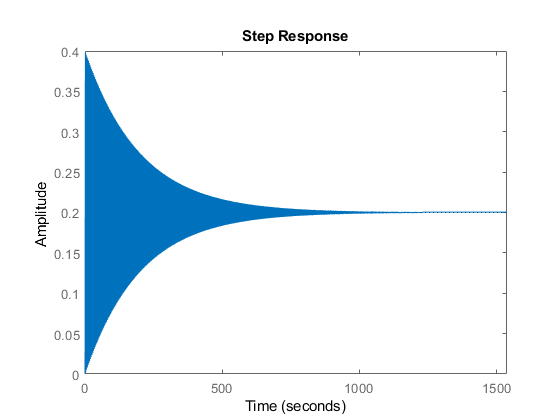

sys=feedback(G,1);
step(sys)

## pg 154

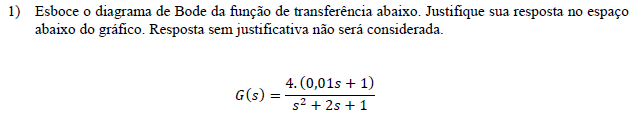

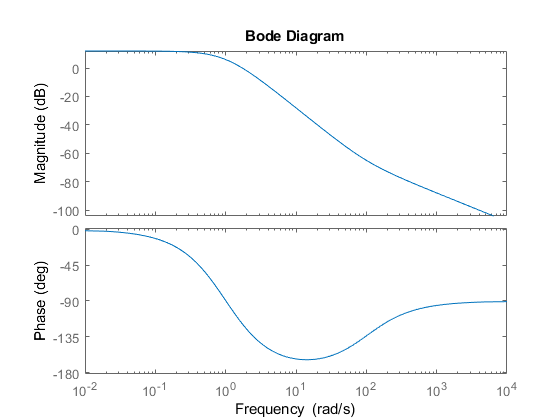

clear; clc; close all;
s=tf('s');
G=4*(0.01*s+1)/(s^2+2*s+1);
bode(G)

## pg 155

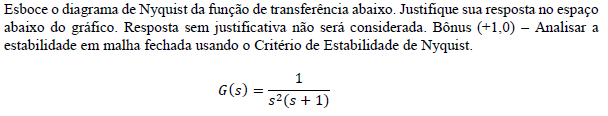

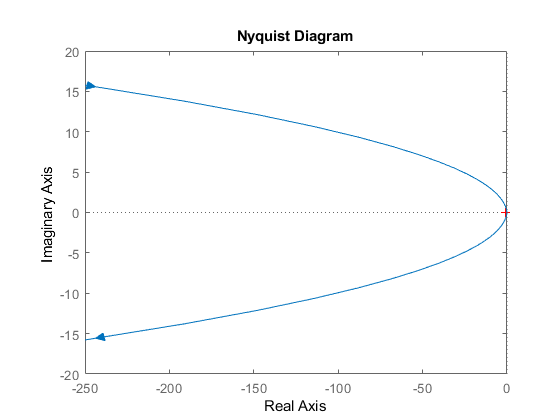

clear; clc; close all;
s=tf('s');
G=1/(s^3+s^2);
nyquist(G)

O diagrama irá circular o ponto -1 no sentido horário para qualquer valor de K, então N=1 sempre. Como P=0, o sistema será sempre instável em malha fechada.

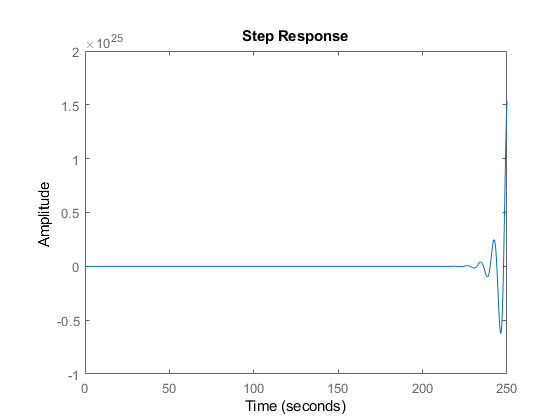

step(feedback(G,1))

## pg 83

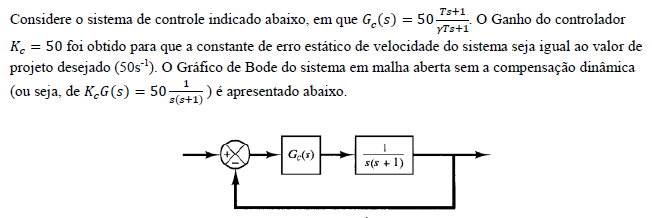

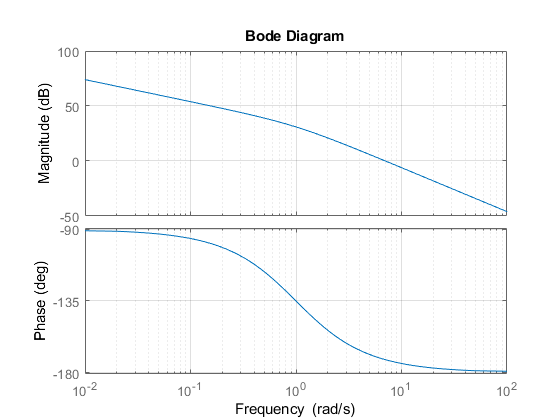

clear; clc; close all;
s=tf('s');
G=1/(s^2+s);
Kc=50;
bode(Kc*G)
grid on

[MG,MF]=margin(Kc*G)

MG = Inf

MF = 8.0895

phi=50-MF+5

phi = 46.9105

alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.1559

[mag,phase,wout] = bode(Kc*G);
modulo=-20*log10(1/sqrt(alfa))

modulo = -8.0722

wc=interp1(20*log10(mag(:)),wout,modulo)

wc = 11.2654

T=1/(sqrt(alfa)*wc)

T = 0.2248

Gav=Kc*(1+T*s)/(1+T*s*alfa)

Gav =
 
  11.24 s + 50
  -------------
  0.03505 s + 1
 
Continuous-time transfer function.



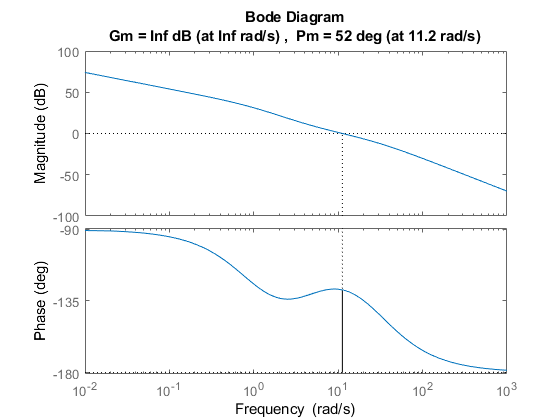

margin(G*Gav)

fase=-(180-50)+6

fase = -124

wc=interp1(phase(:),wout,fase)

wc = 0.6758

modulo=interp1(wout,20*log10(mag(:)),wc)

modulo = 35.7727

beta=10^(modulo/20)

beta = 61.4661

T=10/wc

T = 14.7972

Gat=Kc*(1+s*T)/(1+s*beta*T)

Gat =
 
  739.9 s + 50
  ------------
  909.5 s + 1
 
Continuous-time transfer function.



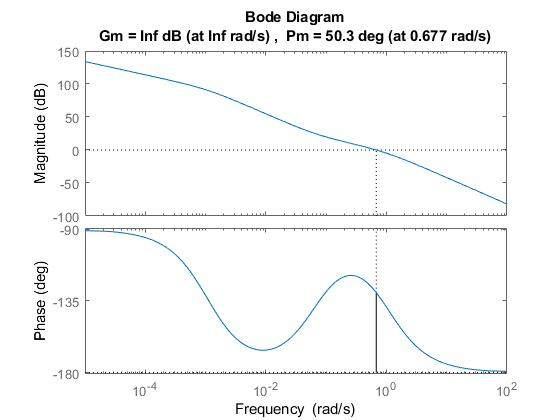

margin(G*Gat)

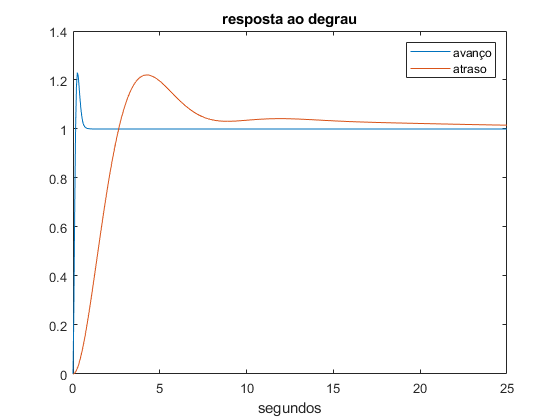

t=linspace(0,25,500);
sysav=feedback(G*Gav,1);
sysat=feedback(G*Gat,1);
yav=step(sysav,t);
yat=step(sysat,t);
plot(t,yav)
hold on
plot(t,yat)
hold off
legend('avanço','atraso')
title('resposta ao degrau')
xlabel('segundos')

O sistema com compensador de avanço é bem mais rápido.

## pg 176

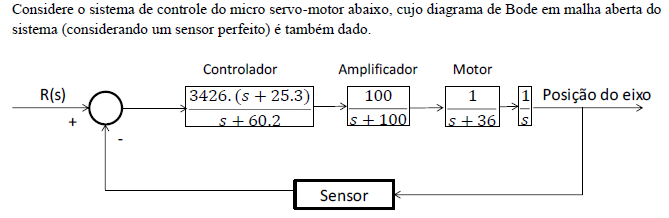

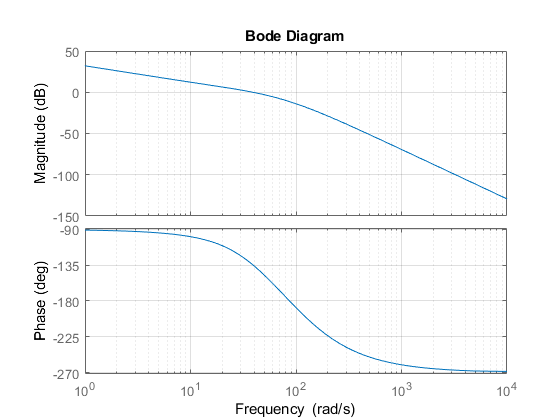

clear; clc; close all;
s=tf('s');
G=3426*(s+25.3)*100/(s+60.2)/(s+100)/(s+36)/s;
bode(G)
grid on

Pelo gráfico: $MG=11.33dB$ e $MF=180º-135.5º=44.5º$

[MG,MF] = margin(G);
fprintf('Margem de ganho=%2.2f dB e Margem de fase=%2.2f º',20*log10(MG),MF)

Margem de ganho=11.34 dB e Margem de fase=45.54 º

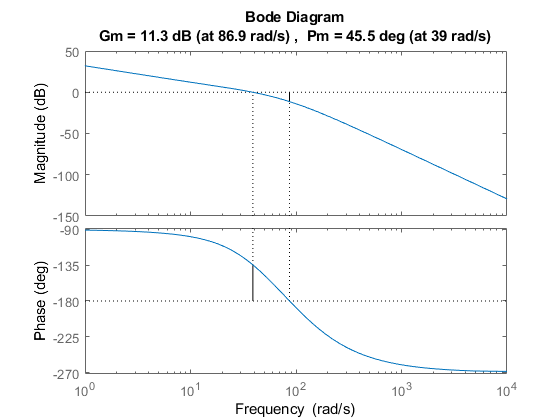

margin(G)

O atraso desloca o gráfico da fase para a direita, alterando a frequência de corte da margem de ganho. O sistema será instável se MF=MG=0. Isso ocorre se em $\omega_c=39rad/s$ a fase for -180º.

Para que isso aconteça, o termo de atraso deverá provocar um atraso de $45.5º\approx\frac{\pi}{4}$ nessa frequência.


$$39T=\frac{\pi}{4}$$


T=pi/4/39

T = 0.0201

O sistema será estável para um atraso menor que 0.02 segundos.

## pg 180

## 

clear; clc; close all;
s=tf('s');
G=60/(s^2+7*s);
Kc=50/60*7

Kc = 5.8333

[Gm,Pm,Wcg,Wcp] = margin(G)

Gm = Inf

Pm = 47.7921

Wcg = Inf

Wcp = 6.3490

beta=Kc % para manter as características originais

beta = 5.8333

T=10/Wcp % para que o calombo do diagrama de fase seja bem antes do wc da MF

T = 1.5751

Gc=Kc*(1+s*T)/(1+s*beta*T)

Gc =
 
  9.188 s + 5.833
  ---------------
    9.188 s + 1
 
Continuous-time transfer function.



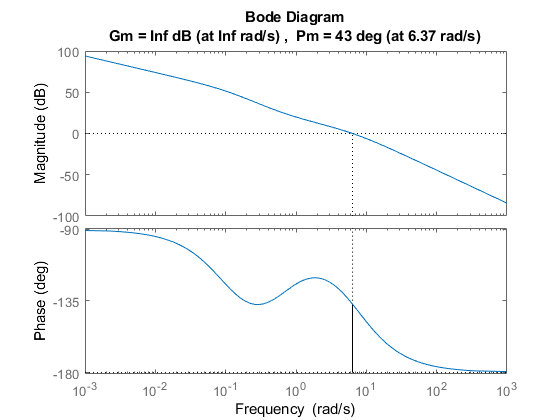

margin(G*Gc)

t=linspace(0,50,100);
sys=feedback(Gc*G,1);
y=step(sys/s,t);
r=step(1/s,t);
erro=(r(end)-y(end));
Kv=1/erro

Kv = 50.0000